# การวิเคราะห์เชิงความถี่

# ตอนที่ 4 : ผลตอบสนองแบบชั่วครู่ และ ผลตอบสนองแบบคงตัว (Transient Response & Steady-state Response)

ระบบพลวัตแบบ LTI (Linear Time-Invariant) และ SISO (Single-Input Single Output) สามารถเขียนอยู่ในรูปของสมการเชิงอนุพันธ์ได้ดังต่อไปนี้


$$a_n \frac{{\mathrm{d}}^n }{\mathrm{d}\;t^n }\left(y\left(t\right)\right)+a_{n-1} \frac{{\mathrm{d}}^{n-1} }{\mathrm{d}\;t^{n-1} }\left(y\left(t\right)\right)+\cdots +a_1 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(y\left(t\right)\right)+a_0 y\left(t\right)=b_m \frac{{\mathrm{d}}^m }{\mathrm{d}\;t^m }\left(u\left(t\right)\right)+b_{m-1} \frac{{\mathrm{d}}^{m-1} }{\mathrm{d}\;t^{m-1} }\left(u\left(t\right)\right)+\cdots +b_1 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(u\left(t\right)\right)+b_0 u\left(t\right)$$


สมการดังกล่าวจะมีผลเฉลยเป็น $y\left(t\right)$ ซึ่งตามหลักการแก้หาผลเฉลยของสมการเชิงอนุพันธ์แบบเชิงเส้น **ผลเฉลยนี้จะประกอบไปด้วย 2 ส่วนซึ่งก็คือ ผลเฉลยเชิงเอกพันธุ์ **$y_h \left(t\right)$** และ ผลเฉลยเฉพาะ **$y_p \left(t\right)$


$$y\left(t\right)=y_h \left(t\right)+y_p \left(t\right)$$


ผลเฉลยเชิงเอกพันธุ์คือผลเฉลยของสมการเชิงอนุพันธ์ที่ไม่มีอินพุตหรือสมการเชิงเอกพันธุ์ (solution of the homoegeneous equation) ซึ่งเมื่อเอาผลเฉ,ยนี้ไปแทนค่าในสมการ เราจะได้ความสัมพันธ์ดังต่อไปนี้


$$a_n \frac{{\mathrm{d}}^n }{\mathrm{d}\;t^n }\left(y_h \left(t\right)\right)+a_{n-1} \frac{{\mathrm{d}}^{n-1} }{\mathrm{d}\;t^{n-1} }\left(y_h \left(t\right)\right)+\cdots +a_1 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(y_h \left(t\right)\right)+a_0 y_h \left(t\right)=0$$


ไม่ว่าจะขยายผลเฉลยนี้มากน้อยเพียงใด ผลลัพธ์จากการแทนค่าของสมการเชิงอนุพันธ์จะทำให้ได้ 0 เสมอ ดังนั้นสมการเชิงอนุพันธ์ที่เป็นเชิงเส้นจะมีผลเฉลยเชิงเอกพันธุ์พ่วงอยู่ด้วยเสมอ 

ส่วนที่จะทำให้สมการเชิงอนุพันธ์เป็นจริงได้นั้นคือผลเฉลยเฉพาะ $y_p \left(t\right)$


$$a_n \frac{{\mathrm{d}}^n }{\mathrm{d}\;t^n }\left(y_p \left(t\right)\right)+a_{n-1} \frac{{\mathrm{d}}^{n-1} }{\mathrm{d}\;t^{n-1} }\left(y_p \left(t\right)\right)+\cdots +a_1 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(y_p \left(t\right)\right)+a_0 y_p \left(t\right)=b_m \frac{{\mathrm{d}}^m }{\mathrm{d}\;t^m }\left(u\left(t\right)\right)+b_{m-1} \frac{{\mathrm{d}}^{m-1} }{\mathrm{d}\;t^{m-1} }\left(u\left(t\right)\right)+\cdots +b_1 \frac{\mathrm{d}}{\mathrm{d}\;t}\left(u\left(t\right)\right)+b_0 u\left(t\right)$$


**ผลเฉลยของสมการเชิงอนุพันธ์เชิงเส้นจะประกอบไปด้วย 2 องค์ประกอบนี้เสมอ**

## ตัวอย่างที่ 1

หากเรากำหนดให้ สมการเชิงอนุพันธ์เป็นดังต่อไปนี้


$$\begin{array}{l}
\dot{y} +k\cdot y=u\\
u\left(t\right)=t
\end{array}$$


โดยที่ $k$ เป็นค่าคงที่ 

เนื่องจากผลเฉลยประกอบไปด้วย $y_h$ และ $y_p$ เราสามารถแก้สมการได้โดยการสร้างสมการเชิงเอกพันธุ์จากสมการที่กำหนดมาให้เพื่อที่จะนำไปแก้หา $y_h$ เมื่อนำ $y_h$ ไปแทนค่าในสมการเชิงอนุพันธ์ เราจะได้สมการดังต่อไปนี้


$${\dot{y} }_h +k\cdot y_h =0$$


จากนั้นเราทำการแก้สมการได้ดังต่อไปนี้


$$\begin{array}{l}
{\dot{y} }_h =-k\cdot y_h \\
\frac{1}{y_h }{\dot{y} }_h =-k\\
\int \left(\frac{1}{y_h }{\dot{y} }_h \right)\mathrm{d}\;t=\int \left(-k\right)\mathrm{d}\;t\\
\ln \left(y_h \right)=-k\cdot t+C_1 \\
y_h ={\mathrm{e}}^{-k\cdot t+C} =C\cdot {\mathrm{e}}^{-k\cdot t} 
\end{array}$$


เราจะได้ว่า 


$$y_h \left(t\right)=C\cdot {\mathrm{e}}^{-k\cdot t}$$


จากนั้น เราสามารถที่จะเดารูปแบบของ $y_p$ ให้อยู่ในรูปที่คล้ายกับ $u\left(t\right)$ ได้ เนื่องจาก $u\left(t\right)$ เป็นฟังก์ชันพหุนามกำลังหนึ่ง เราจะเดาให้ $y_p$ อยู๋ในรูปพหุนามกำลังหนึ่งกังต่อไปนี้


$$y_p \left(t\right)=A\cdot t+B$$


เมื่อเราเอาไปแทนสมการเชิงอนุพันธ์ เราจะได้สมการความสัมพันธ์ดังต่อไปนี้


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}\;t}\left(A\cdot t+B\right)+k\cdot \left(A\cdot t+B\right)=t\\
A+k\cdot A\cdot t+k\cdot B=t
\end{array}$$


หากเราจับคู่ความสัมพันธ์ของสัมประสิทธิ์ เราจะได้ระบบสมการดังต่อไปนี้


$$\begin{array}{l}
k\cdot A=1\\
A+k\cdot B=0
\end{array}$$


เมื่อเราแก้ระบบสมการดังกล่าวเราจะได้ว่า


$$\begin{array}{l}
A=\frac{1}{k}\\
B=-\frac{A}{k}\\
B=-\frac{1}{k^2 }\\

\end{array}$$



$$y_p \left(t\right)=\frac{1}{k}t-\frac{1}{k^2 }$$


ดังนั้นผลเฉ,ยของสมการเชิงอนุพันธ์จะเขียนอยู๋ในรูปผลบวกของ $y_h$ และ $y_p$ ดังต่อไปนี้


$$y\left(t\right)=\left\lbrack C\cdot {\mathrm{e}}^{-k\cdot t} \right\rbrack +\left\lbrack \frac{1}{k}t-\frac{1}{k^2 }\right\rbrack$$


ในเชิงของระบบพลวัต ตัวระบบเองนั้นถูกจำลองในรูปแบบของสมการเชิงอนุพันธ์ และผลเฉลยของสมการเชิงอนุพันธ์นั้นก็คือ ผลตอบสนอง (response) ของระบบ 

**ระบบพลวัตแบบ LTI (Linear Time-Invariant) และ SISO (Single-Input Single Output) นั้นจะประกอบไปด้วยผลตอบสนอง 2 ส่วนด้วยกันซึ่งได้แก่**

- **ผลตอบสนองแบบชั่วครู่ (transient response) **$y_t \left(t\right)$

- **ผลตอบสนองแบบคงตัว (steady-state response) **$y_s \left(t\right)$

ซึ่งในเชิงของสมการอนุพันธ์ ผลตอบสนองแบบชั่วครู่ก็คือผลเฉลยเชิงเอกพันธุ์ และผลตอบสนองแบบคงตัวคือผลเฉลยเฉพาะ นอกจากคุณสมบัติทางคณิตศาสตร์แล้ว เราสามารถอธิบายความหมายของผลตอบสนองแต่ละส่วนในเชิงของระบบพลวัตได้อีกด้วย

เมื่อระบบพลวัตถูกกระตุ้นด้วยอินพุต ระบบจะเปลี่ยนไปตามธรรมชาติของระบบเอง ธรรมชาติของระบบนี้จะเกิดขึ้นทันทีและเป็นการเปลี่ยนแปลงที่"อาจ"จะเกิดขึ้นแค่ชั่วขณะ เนื่องระบบพลวัตมีการเปลี่ยนแปลงตามเวลาและมีสถานะที่ไม่อยากจะเปลี่ยนกระทันหันได้ ระบบจึงมีผลตอบสนองตามธรรมชาติของมัน

นอกจากนั้นระบบพลวัตเองก็ต้องเปลี่ยนแปลงไปตามอินพุต มันจึงไม่แปลกระบบจะมีผลตอบสนองแบบคงตัวที่มีลักษณะคล้ายกับอินพุต

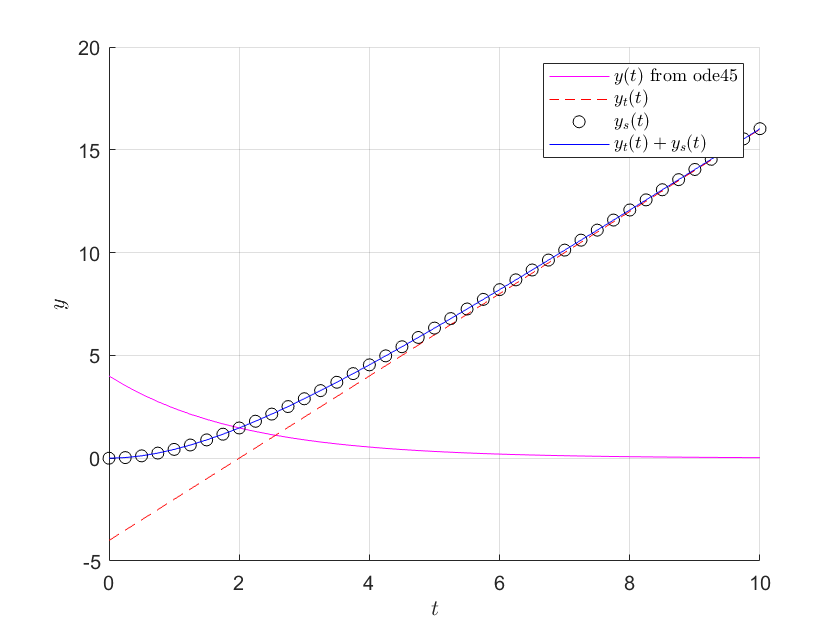

k = 0.5;
t_max = 10;
tspan = [0 t_max];
y0 = 0;
u = @(t)t;
[t,y] = ode45(@(t,y)-k*y+u(t),tspan,y0); %[t,y] = ode45(odefun,tspan,y0), where tspan = [t0 tf], integrates the system of differential equations y′=f(t,y) from t0 to tf with initial conditions y0. Each row in the solution array y corresponds to a value returned in column vector t.
y_s = t/k-1/k^2;
y_t = (1/k^2+y0)*exp(-k*t);
clf
ax = axes;
hold(ax,'on');
grid(ax,'on')
plot(ax,t,y_t,'m')
plot(ax,t,y_s,'r--')
plot(ax,t,y_t+y_s,'ko')
plot(ax,t,y,'b')
xlabel('$t$','Interpreter',"latex");
ylabel('$y$','Interpreter',"latex");
legend({'$y(t)$ from ode45','$y_t(t)$','$y_s(t)$','$y_t(t)+y_s(t)$'},'Interpreter',"latex")

เมื่อเราทำการวิเคราะห์ระบบพลวัต **เราสามารถที่จะศึกษาในแต่ละส่วนของผลตอบสนองแยกกัน หากเราต้องการที่จะวิเคราะห์ผลตอบสนองเชิงเวลา เราจะทำการศึกษาเฉพาะในส่วนของผลตอบสนองแบบชั่วครู่y_t(t)**

**แต่เราต้องการที่จะวิเคราะห์ผลตอบสนองเชิงความถี่ เราจะทำการศึกษาเฉพาะในส่วนของผลตอบสนองแบบคงตัว y_s(t)**